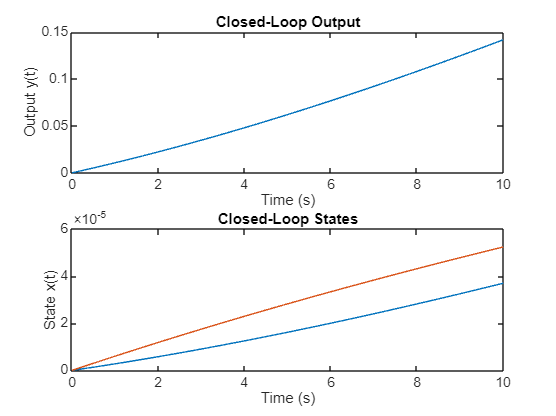

Q = eye(2);
R = 1; 
K = lqr(A, B, Q, R); 

A_cl = A - B * K;  % Closed-loop system matrix
B_cl = B;  % No change to input matrix
C_cl = C;  % Same output matrix
D_cl = D;  % Same direct transmission

sys_cl = ss(A_cl, B_cl, C_cl, D_cl);  % Closed-loop state-space system

% Simulate the response to a step input (example)
t = 0:0.01:10;  % Time vector
u = ones(size(t));  % Step input (e.g., unit step)
[y, t, x] = lsim(sys_cl, u, t);  % Simulate the closed-loop system

% Plot the output and state
figure;
subplot(2, 1, 1);
plot(t, y);
title('Closed-Loop Output');
xlabel('Time (s)');
ylabel('Output y(t)');

subplot(2, 1, 2);
plot(t, x);
title('Closed-Loop States');
xlabel('Time (s)');
ylabel('State x(t)');